================================================================================

# Práctica 9. Splines y DFT

#### **Ejercicio 1. Interpolación con funciones de MATLAB **

La función de MATLAB `interp1(x,v,xq,method) `calcula por defecto una spline lineal. Permite especificar el método de interpolación: '`nearest`', '`next`', '`previous`', '`linear`', '`spline`', '`pchip`', '`makima`' o '`cubic`'.

El objetivo es diferenciar entre un polinomio interpolador, una spline lineal y distintas splines cúbicas.

clear all
xdata = -4:5; 
ydata = [0 0.2 0 0.9 0.8 1 0 0.3 0.3 0];

En un plot mismo dibujar:

- Los datos como asteriscos rojos.

- El polinomio interpolador en magenta (se puede usar $\texttt{polyval()}$ como en la práctica anterior).

- La spline lineal en negro.

- La spline cúbica "not-a-knot" en verde.

- La spline cúbica de Hermite en azul.

- La spline con preservación de forma cúbica de Hermite con Akima modificado en cian.

#### Ejercicio 2. Spline cúbica

Comprobar que la función siguiente 


$$g(x) = \begin{cases}
1+x-x^2, & 0\leq x<1\\
1-2(x-1)-3(x-1)^2+4(x-1)^3, & 1\leq x <2\\
4(x-2)+9(x-2)^2-3(x-2)^3, & 2\leq x\leq 3
\end{cases}$$


es una spline cúbica que interpola en los puntos $(0,1)$, $(1,1)$, $(2,0)$, y $(3,10)$ y comprobar hasta qué derivada hay continuidad en cada punto.

clear all
xknot=[0 1 2 3]; 
yknot=[1,1,0,10];

#### Ejercicio 3. DFT para identificar las notas de un acorde

Tenemos un sonido que corresponde a un acorde. Vamos a usar la DFT para averiguar las notas del acorde. 

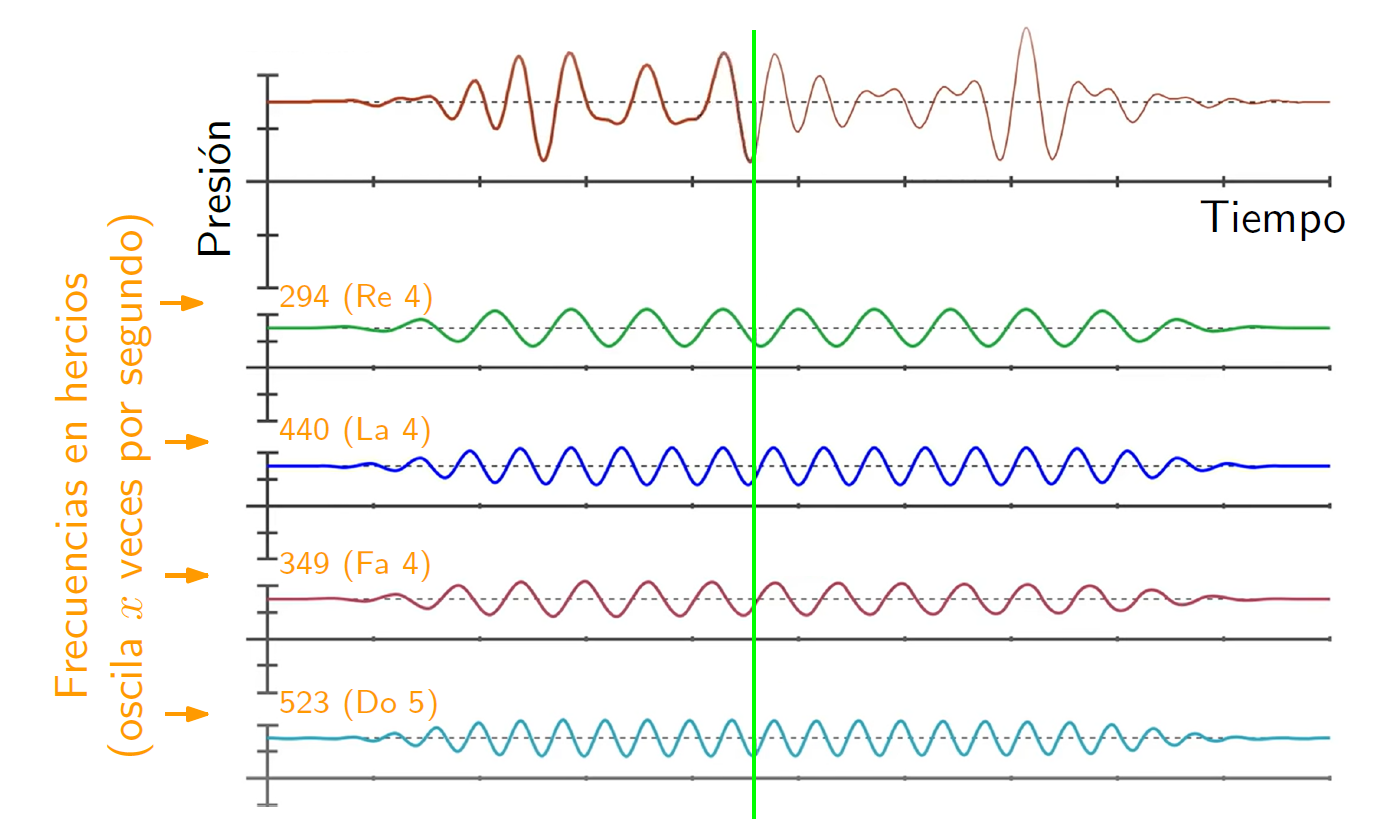

Construir la señal $X$ discretizada como la suma del siguientes señales sinusoidales (para este problema no nos importan las fases por lo que podemos usar por ejemplo cosenos sin desfase):

- una de frecuencia 294 y amplitud 5

- una de frecuencia 440 y amplitud 4

- una de frecuencia 349 y amplitud 2

- una de frecuencia 523 y amplitud 3

Para la discretización asumimos que sampleamos durante un segundo a 2000 Hz. (Esto es suficiente en nuestro caso pero muy por debajo de las tasas de muestreo que se usan en la realidad. El oido humano escucha frecuencias entre los 20 y los 20.000 Hz. Una frecuencia de muestreo para señales de audio muy habitual es 44,1 kHz, lo cual aproximadamente concuerda con lo que esperariamos usando el teorema de Nyquist-Shannon.)

clear all


Hacer un plot de la señal sampleada. 

Aplicar la DFT para crear un vector $\mathbf{v}$ con los coeficientes que nos da la DFT:  $\hat{f}_k= n\cdot c_k = \sum_{j=0}^{n-1} f(t_j)\omega_n^{kn} \text{ con } \omega_n = e^{-i\frac{2\pi}{n}}
$ (donde $n$ es el número de puntos en la discretización y los $f(t_j)$ son los valores en $X$). Obtener tambien el vector de coeficientes $\mathbf{c} = (c_0, c_1, \ldots)$ y hacer un plot de sus valores absolutos.

Si miramos atentamente el plot anterior, vemos que *casi* tenemos la información que estábamos buscando: se han identificado correctamente las frecuencias de las cuatro notas y (la mitad de) sus amplitudes. Pero aparecen, simétricamente otros cuatro valores lejanos a cero... Lo que está sucediendo es que la serie $$f(t) = \frac{a_0}{2} + \sum_{k=1}^{\infty} a_k \cos\left(\frac{2\pi k}{T} t\right) + b_k \sin\left(\frac{2\pi k}{T} t\right) = \sum_{k=-\infty}^{\infty} c_k e^{\frac{2\pi ki}{T} t}$$ con $c_k = \frac{a_k - ib_k}{2}$ incluye en las $c_k$s coeficientes de frecuencias negativas! 

Si $f(t)$ es real se cumple:

• Las coeficientes de frecuencias negativas, se obtienen complejo-conjugando los coeficientes de frecuencias positivas. Por eso, en este caso solo necesitamos las frecuencias positivas.

• Obtenemos$\lfloor{{n}/{2}}\rfloor + 1$coeficientes distintos que corresponden con $\lfloor{{n}/{2}}\rfloor$ frecuencias positivas distintas, o ($\lfloor{{n}/{2}}\rfloor + 1$ si consideramos $c_0$ como una frecuencia).

Hacer ahora el plot de los valores $2|c_k| = |a_k - ib_k|$  para las primeras $\lfloor{{n}/{2}}\rfloor + 1$ frecuencias y ver que se corresponden con las notas que formaban nuestra onda. (Por ejemplo se pueden extraer los valores con $c_k$>0.1.)

#### Ejercicio 4. FFT para eliminar el ruido

Tenemos una señal que es la suma de ondas sinusoidales de dos frecuencias pero que tiene mucho ruido: más que las amplitudes de estas ondas. Vamos a ver que usando la transformada de Fourier ¡podemos filtrar ese ruido!

Construir la señal $f(t) = \sin (2\pi50t) + \sin (2\pi120t)$ con $t\in [0,1]$ y discretizarla con intervalos de tiempo $dt = 0.001$. Guardar estos datos como $X_{limpia}$. Sumar a cada valor de este conjunto discreto de datos ruido aleatorio en $[0,2.5]$. Guardar estos datos como $X_{ruido}$. Representar los datos con ruido en rojo y luego en la misma gráfica los datos limpios en azul.

clear all


Usar ahora la implementación de Matlab de la FFT (función $\texttt{fft(X\_{ruido},n)}$ donde $n$ es el número de datos) para calcularla; la llamamos $\hat{\mathbf{f}}$.

Vamos ahora a determinar la potencia de cada frecuencia, lo que se conoce como espectro de potencia (PS), para encontrar aquellas frecuencias con mucha potencia y filtrar el resto. A partir de la FFT obtenida, el PS se puede calcular multiplicando cada valor en $\hat{\mathbf{f}}$ por su complejo conjugado y dividiendo entre $n$. Calcular el PS.

Representar ahora el PS, con las frecuencias en hercios en el eje $x$. Como en el ejercicio anterior, dibujar solo las primeras $\lfloor{{n}/{2}}\rfloor + 1$ frecuencias. Puede ayudar usar que la frecuencia base o fundamental $f_{fun}$ en hercios es la frecuencia de muestreo $f_s$ dividida entre el número de muestras $n$: $f_{fun} = \frac{f_s}{n}$. Los harmónicos son múltiplos de esta frecuencia.

Usar el PS para filtrar el ruido: encontrar aquellas frecuencias con potencia $>100$ y hacer cero el resto en un vector $PS_{limpio}$. Comprobar el filtrado graficamente. 

Aplicar el filtrado a  $\hat{\mathbf{f}}$, haciendo cero sus componentes con frecuencias filtradas.

Recuperar ahora la señal filtrada usando la transformada de Fourier inversa que da MATLAB con $\texttt{ifft()}$. Representar otra vez los datos limpios en azul y, en la misma gráfica, representar la señal filtrada en verde. Comprobar que coinciden.

#### Funciones internas

`Documento preparado por I. Parada, 24 de abril de 2024`